## Extract Trace Samples using Map Reduce

Requires the exported service samples of alibaba2020ms.mlx

[service_samples_export_file, ~, ~, ~, ~, ~, ~, ~] = config()

service_samples_export_file = "../sampled_services_export.mat"

load('-mat', service_samples_export_file);
service_samples = export;
clear export;
disp(service_samples);

     service_id      cluster    trace_factor                                                                         involved_ms                                                                     
    _____________    _______    ____________    _____________________________________________________________________________________________________________________________________________________

    "S_79946648"        1         0.098634      {["MS_40139"    "MS_45753"    "USER"                                                                                                               ]}
    "S_62583430"        1         0.098634      {["MS_58809"    "MS_9076"    "USER"                                                                                                                ]}
    "S_6505908"         1         0.098634      {["MS_13825"    "MS_578

clear service_samples_export_file;

### Parallelism

Parts of this script profit from parallel execution (requires Parallel Computing Toolbox)

**Run only one of two sections below...**

### Enabling parallel computing

Run this scetion to (re-)enable parallel mapreducing

Note: The debugger will not work within map-reduce parts while this is ON

mapreducer(gcp);

Starting parallel pool (parpool) using the 'Processes' profile ...
Parallel pool using the 'Processes' profile is shutting down.



### Disabling parallel computing

Run this scetion to disable parallel mapreducing

Note: This will allow the debugging of map-reduce parts.

mapreducer(0);

## Actual Script below

### Prepare selected columns

We may not care about certain columns, once we fully understand the trace data.

[trace_header, trace_formats, trace_vartypes] = constants();
ignore_columns = ["response_time"];
used_col_idx = ~ismember(trace_header, ignore_columns);
trace_selected_cols = trace_header(used_col_idx);
trace_selected_vartypes = trace_vartypes(used_col_idx);
trace_selected_formats = trace_formats(used_col_idx);

clear trace_formats;
clear trace_vartypes;
clear ignore_columns;

### Create Datastore

Read in .csv and create a datastore that can be used with mapreduce.

[~, trace_location, trace_header_lines, ~, ~, ~, ~, ~] = config()
ds = tabularTextDatastore(trace_location, "NumHeaderLines", trace_header_lines, ...
    "RowDelimiter", "\n", ...
    "Delimiter", ",", ...
    "TreatAsMissing", "None", ...
    "MissingValue", 0, ...
    "VariableNames", trace_header, ...
    "SelectedFormats", trace_selected_formats, ...
    "SelectedVariableNames", trace_selected_cols);

clear trace_location;
clear trace_header_lines;
clear trace_selected_formats;

prev_ds = copy(ds);
reset(prev_ds);
prev_ds.ReadSize = 10;
read(prev_ds)
clear prev_ds;

### Map Reduce to find valid trace ids

This section filters for valid traces.

To reduce the memory useage the main part of the script is executed once per service. This does take long however it allows intermediate results.

Validation Criteria:

- service_id is a member of our sampled selection

- upstream_ms must be in the list of involved MS or equal "USER"

- downstream_ms must be in the list of involved MS

- The rpc_id parent of every entry of one trace_id is present

- All entries of a trace_id are connected to the "USER" upstream entry

[~, ~, ~, full_traces_dir, ~, ~, ~, ~] = config();
col_idx_trace_id = strcmp(trace_header, "trace_id") > 0;

from_idx = 1;
to_idx = height(service_samples);

% wrap reducer function to pass empty table obj
empty_table = table('Size', [0 length(trace_selected_vartypes)], 'VariableTypes',trace_selected_vartypes, 'VariableNames',trace_selected_cols);
reduceFunc = @(a, b, c)trace_reducer(a, b, c, empty_table);

fprintf("*********** Running for services %i to %i ***********\n", from_idx, to_idx);
last_dur = 300.00;
for i=from_idx:to_idx
    time_est = last_dur * ((to_idx + 1) - i);
    fprintf("Estimated Time remaining: %fs\n", time_est);

    tic;
    service_id = service_samples.service_id{i};
    involved_ms = service_samples.involved_ms{i};
    fprintf("*********** (%i/%i) Getting traces for '%s' ***********\n", i, to_idx, service_id);

    % wrap mapper function to pass variable context
    mapFunc = @(a, b, c)trace_mapper(a, b, c, col_idx_trace_id, service_id, involved_ms);
    
    ds_idx = i + 1 - from_idx;
    tmp_ds = mapreduce(ds, mapFunc, reduceFunc, 'OutputFolder', './results', 'Display', 'off');

    fprintf("*********** (%i/%i) Creating CSV for '%s' ***********\n", i, to_idx, service_id);
    entries = readall(tmp_ds);
    flatter = vertcat(entries{:,2});
    even_flatter = sortrows(vertcat(flatter{:,1}), "timestamp", "ascend");
    file_name = full_traces_dir + "/traces_" + num2str(i, "%03i") + "_" + service_id + ".csv";
    writetable(even_flatter, file_name, "Delimiter", "\t");
    last_dur = toc;

    clear entries;
    clear flatter;
    clear even_flatter;

    fprintf("*********** (%i/%i) took %fs ***********\n", i, to_idx, last_dur);
end

clear full_traces_dir;
clear col_idx_trace_id;
clear empty_table;
clear mapFunc;
clear reduceFunc;

### Read 'all traces' and append their service_id+cluster

tic
full_traces = read_full_traces(service_samples, true);
toc

figure;
histogram(round(full_traces.timestamp / 1000), 3600);
title("Trace count over 3600s");
ylabel("Full trace Count");
xlabel("Seconds");

Overall incoming trace count is rather stable.

trace_analysis_plots(full_traces, {[1 power(10,4)] "log"});

We can spot variety within the traffic per cluster. It does not contain a massive burst or "once in a lifetime" load. Such a workload development could be modeled in future research.

### Sample from full_traces

rng(161,"philox");
tic
sampled_traces = read_full_traces(service_samples, false);
toc

Elapsed time is 15.081870 seconds.


#### Basic plot

figure;
histogram(round(sampled_traces.timestamp / 1000), 3600);
title("Trace count over 3600s");
ylabel("Sampled trace Count");
xlabel("Seconds");

Overall incoming trace count is rather stable with some exceptions.

#### Plot trace counts by cluster

trace_analysis_plots(sampled_traces, {[1 power(10,2.2)] "log"});

Either: Further reducing the trace count by sampling from it loses the charactersitics of the trace.

Or: We see the dominance of [19, 35] + could include [1, 5, 27, 28]

Or: We just take it as it is.

### Deployment process

How will we roll out?

Scheduling is the act of allocating resources (in a running system) - we want to mainly judge the running system, however realistically something is already running when scheduling, not everything is run at the same time.

Maybe we can find out WHEN a microservice is first used and roll them out as they come.

involved_ms_with_ts = get_involved_ms_with_ts(sampled_traces);
ms_deploy_ts = sortrows(groupsummary(involved_ms_with_ts, "involved_ms", "min", "timestamp"), "min_timestamp", "ascend");

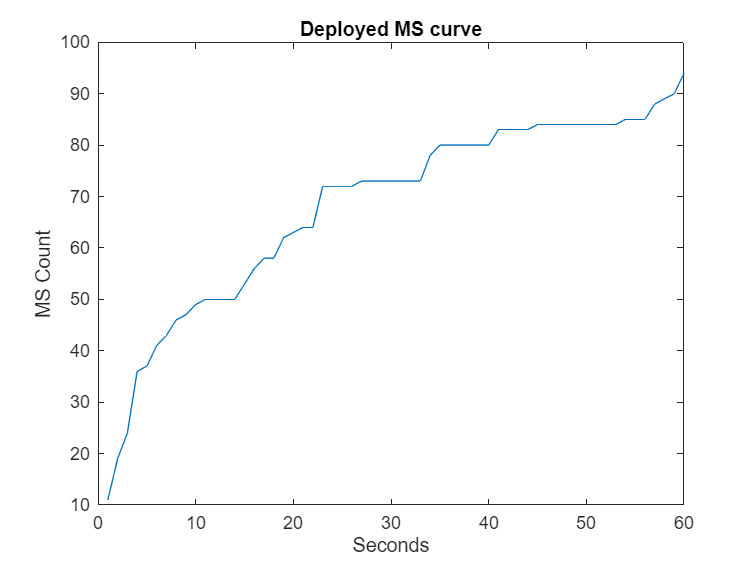

ts = round(ms_deploy_ts.min_timestamp / 60000);
% deployed ms count (over 60 min)
cumulativeCounts = cumsum(histcounts(ts, 60));
figure;
plot(cumulativeCounts);
title("Deployed MS curve");
ylabel("MS Count");
xlabel("Seconds");

Good news: We can consecuteively roll-out the microservices, while we already have load on the system.

CHEER!

clear ts;
clear cumulativeCounts;

### Create MS deploy timestamp CSV

[~, ~, ~, ~, ~, ~, ~, deployment_ts_output_file] = config();
ms = k8s_conformous(ms_deploy_ts.involved_ms);
required_at = ms_deploy_ts.min_timestamp;
export = table(ms, required_at)

export = 94×2 table
         ms         required_at
    ____________    ___________

    {'ms-41385'}         878   
    {'ms-15284'}         908   
    {'ms-28467'}         908   
    {'ms-37691'}         908   
    {'ms-53154'}        2825   
    {'ms-10207'}        4411   
    {'ms-25004'}        7759   
    {'ms-20383'}       22927   
    {'ms-28050'}       22927   
    {'ms-51863'}       22927   
    {'ms-51682'}       24514   
    {'ms-5182' }       48229   
    {'ms-21093'}       70172   
    {'ms-69235'}       70172   
    {'ms-40139'}       73197   
    {'ms-45753'}       73197   


fprintf("Writing '%s'", deployment_ts_output_file);

Writing '../sampled_deployment_ts.csv'

writetable(export, deployment_ts_output_file, "Delimiter", "\t", "QuoteStrings","none");
clear deployment_ts_output_file;

### Create service graph json file

required by muBench to template necessary k8s yaml files.

[~, ~, ~, ~, ~, service_graph_output_file, ~, ~] = config();
fprintf("Writing '%s'", service_graph_output_file);
create_service_graph_parameters_for_mbench(ms_deploy_ts.involved_ms, service_graph_output_file);
clear service_graph_output_file;

### Create sampled traces CSV

% Some traces have two ms-xyz after the 'USER' node. 
% We need to split these up
export = export_traces_for_mubench(sampled_traces)
[~, ~, ~, ~, ~, ~, trace_csv_output_file, ~] = config();
fprintf("Writing '%s'", trace_csv_output_file);

Writing '../sampled_traces.csv'

writetable(export, trace_csv_output_file, "Delimiter", "\t", "QuoteStrings","none");
clear trace_csv_output_file;